# Lab 3

## Kurt Delegard

## PHYS 434 AB

### Time spent drafting: 8 hours

### Problem 1.

*In our first example we are looking at the temperature reading (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12 Kelvin to within the 0.4 degree precision of the thermometry and the thermal control system (standard deviation). However, there are times when the thermal control system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and we just had a wonky reading, in an abundance of caution we want to throw those values out too.*

Assuming the temperature fluctuations form a Gaussian distribution, we can model the temperature data as a Gaussian distribution with a mean of 12 K and a standard deviation of 0.4:

clear;
clc;
clf;

mu = 12;
sig = 0.4;

xs = linspace(0, 24, 1000);
temp = makedist("Normal", "mu", mu, "sigma", sig);

To make this scenario more realistic, we will add in "bad" data - intentional outliers that are far away from the mean of the temperature distribution.

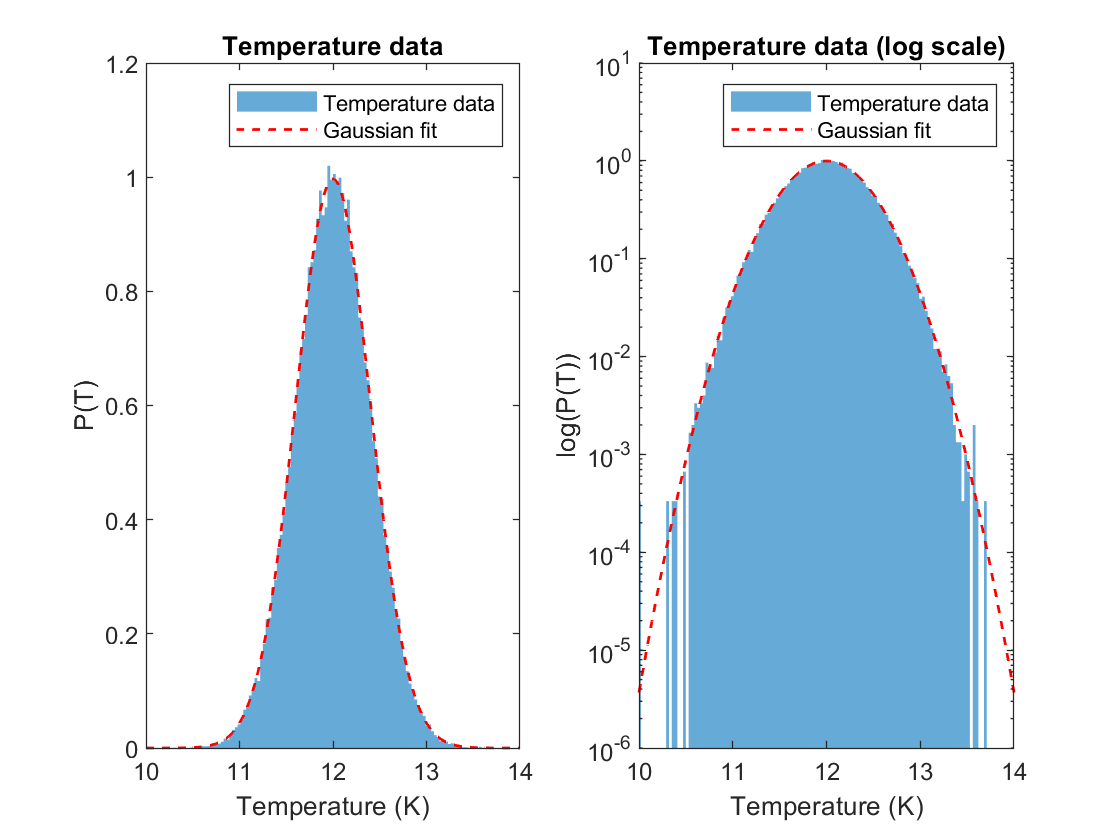

bad_data = [10. 10.3 2.1 0. 0. 15.6 22.3 12.7];
good_data = random(temp, [1, 100000]);

%Total temperature data = good data + bad data
full_data = [good_data, bad_data];

%Gaussian distribution fit
normys = normpdf(xs, mu, sig);

subplot(1, 2, 1);
histogram(full_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor', 'none'), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);

xlim([10, 14])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('P(T)')
title('Temperature data');
subplot(1, 2, 2);
histogram(full_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor',"none"), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);
set(gca,'YScale','log')

xlim([10, 14])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('log(P(T))')
title('Temperature data (log scale)')

This data seems to pretty accurately follow a Gaussian trend. However, zooming out to see the full range of data:

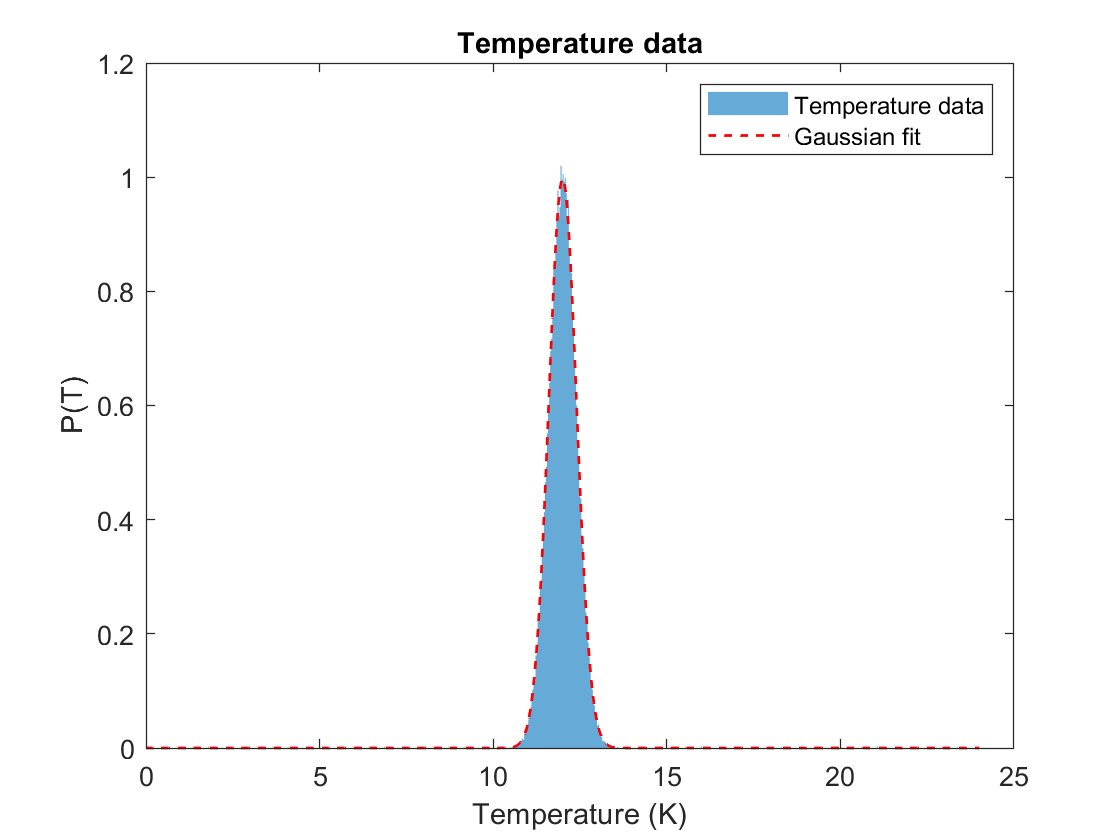

clf;

histogram(full_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor', 'none'), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);

xlim([0, 25])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('P(T)')
title('Temperature data');

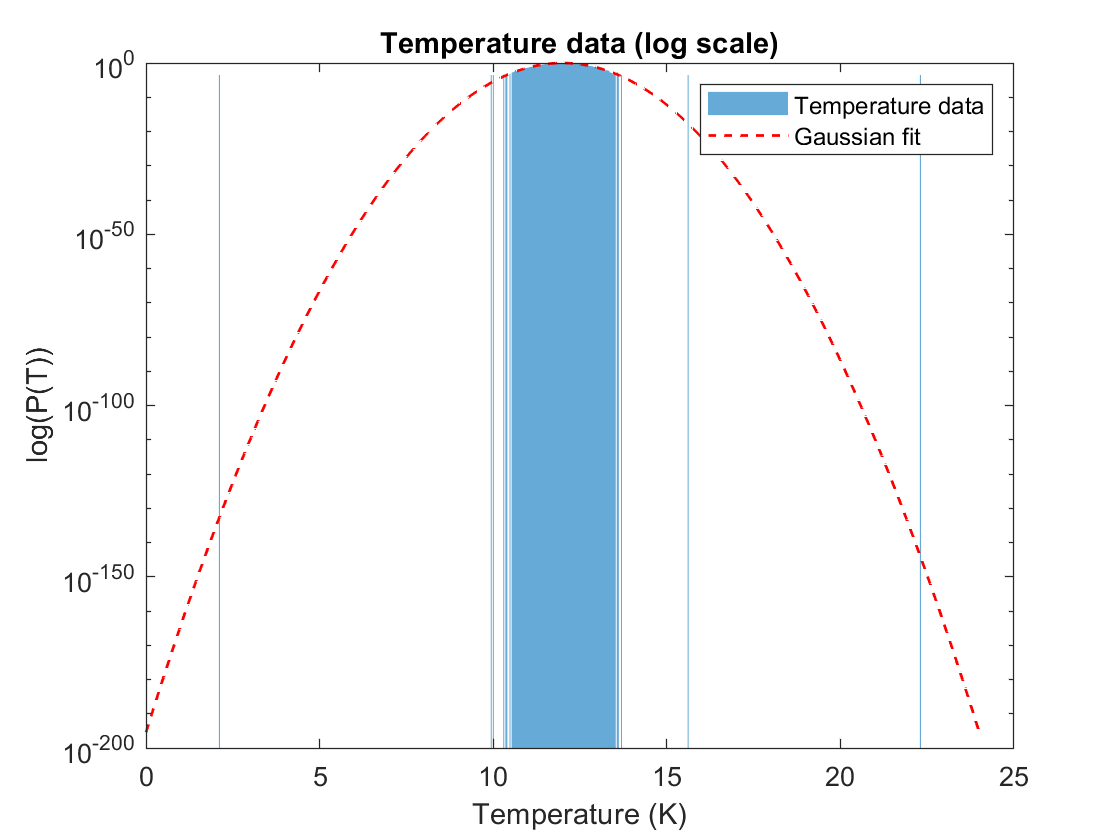


clf;
histogram(full_data, 'Displaystyle', 'bar', 'Normalization', "pdf", 'EdgeColor',"none"), hold on;

plot(xs, normys, 'r--', 'LineWidth', 1);
set(gca,'YScale','log')

xlim([0, 25])
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('log(P(T))')
title('Temperature data (log scale)')

There are several outliers (which we added in) that could cause problems in our analysis.

We want to identity the bad data and exclude it from our results. We know that our good data should fall very close to the mean of the distriution, T = 12 K, so we should define bad data points as points that are a certain distance away or more from the mean.

First, let's try to define the outliers in this data. Say, to begin with, we want to only keep the data within $\pm 5\sigma$ of the mean. Can we find the outliers that exceed this range of values?

threshold = 5 * sig;
outliers = full_data(full_data < (mu - threshold) | full_data > (mu + threshold))

outliers =     9.9470    2.1000         0         0   15.6000   22.3000


While this correctly determines some of the outliers that we added, it did not pick out all of them. We are trying to find an optimal value of $X*\sigma$ that removes all our bad data (true negatives) and keeps all our good data (true positives). We would in turn like to avoid any instances of omission, where we accidentally remove good data (false negatives), as well as comission, where we accidentally include bad data (false positives.)

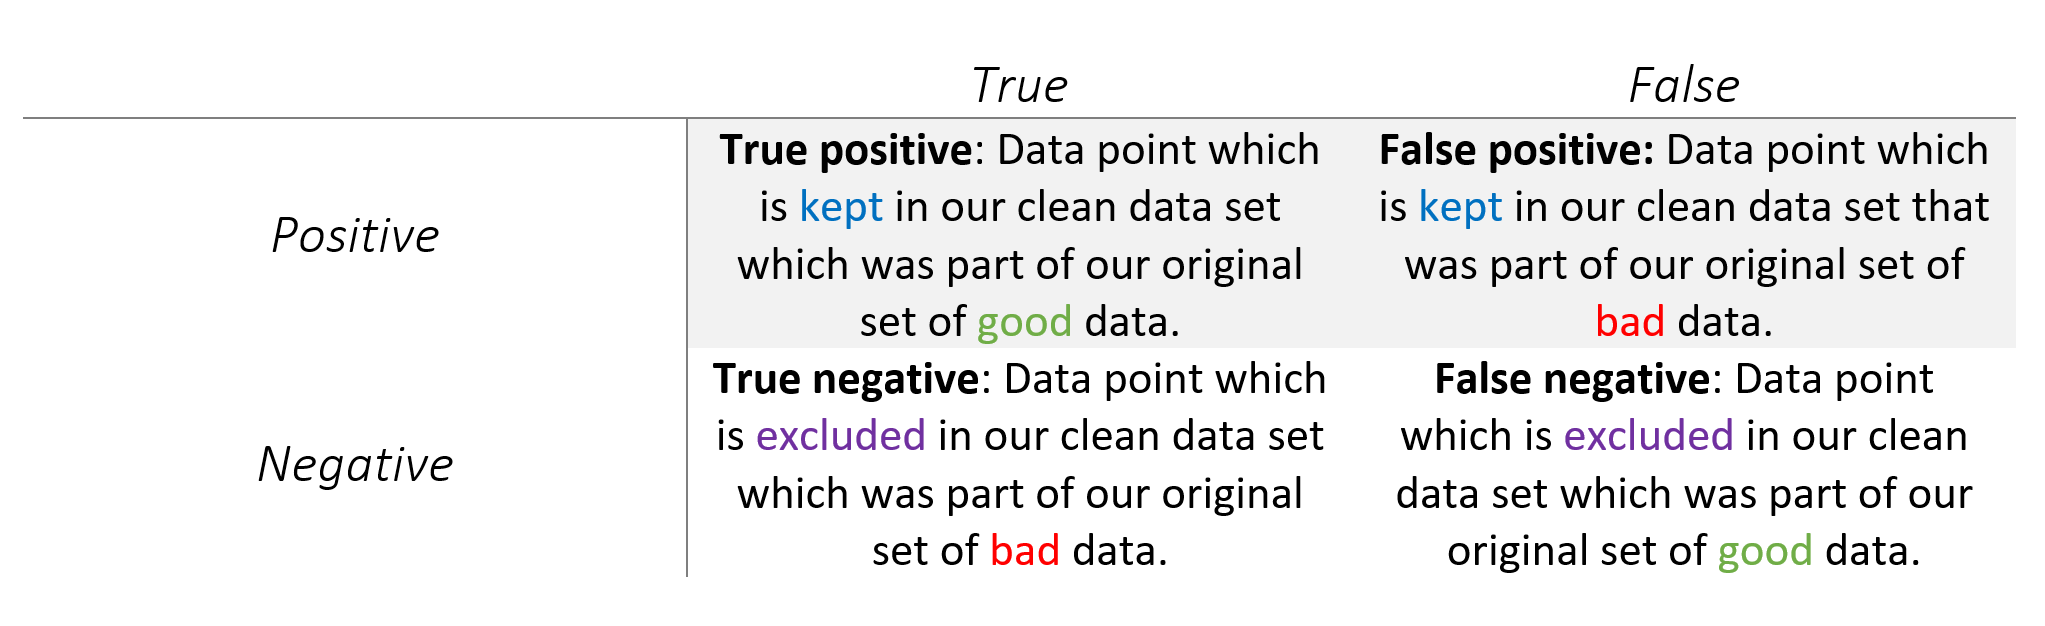

Therefore, we must pose the question: **What is the optimal distance **$X*\sigma$ **away from the mean that keeps the greatest number of true data points and the smallest number of false data points? **

Mathematically, we can represent this statistical question as finding x such that, after excluding what we think is bad data, we have kept the maximum number of good data points and have kept the minimum number of bad data points, or outliers.

Let $g\left(x\right)$represent the number of good data points defined for a value x (since $\sigma$ does not change in this problem, we can simply find the optimal value of x). Similarly, let $b\left(x\right)$ represent the number of bad data points defined by a value x. We want to find $X_{\mathrm{opt}} \;\mathrm{such}\;\mathrm{that}\;g\left(X_{\mathrm{opt}} \right)=\mathrm{max}\left(g\left(x\right)\right)$ and $X_{\mathrm{opt}} \;\mathrm{such}\;\mathrm{that}\;b\left(X_{\mathrm{opt}} \right)=\mathrm{min}\left(b\left(x\right)\right)$.

One approach we can take is to plot the number of true positives, true negatives, false positives, and false negatives versus the selection criteria $X*\sigma$. (I will plot the x-axis as $X$ since $\sigma$ does not change and thus only acts to linearly scale the x-axis.)

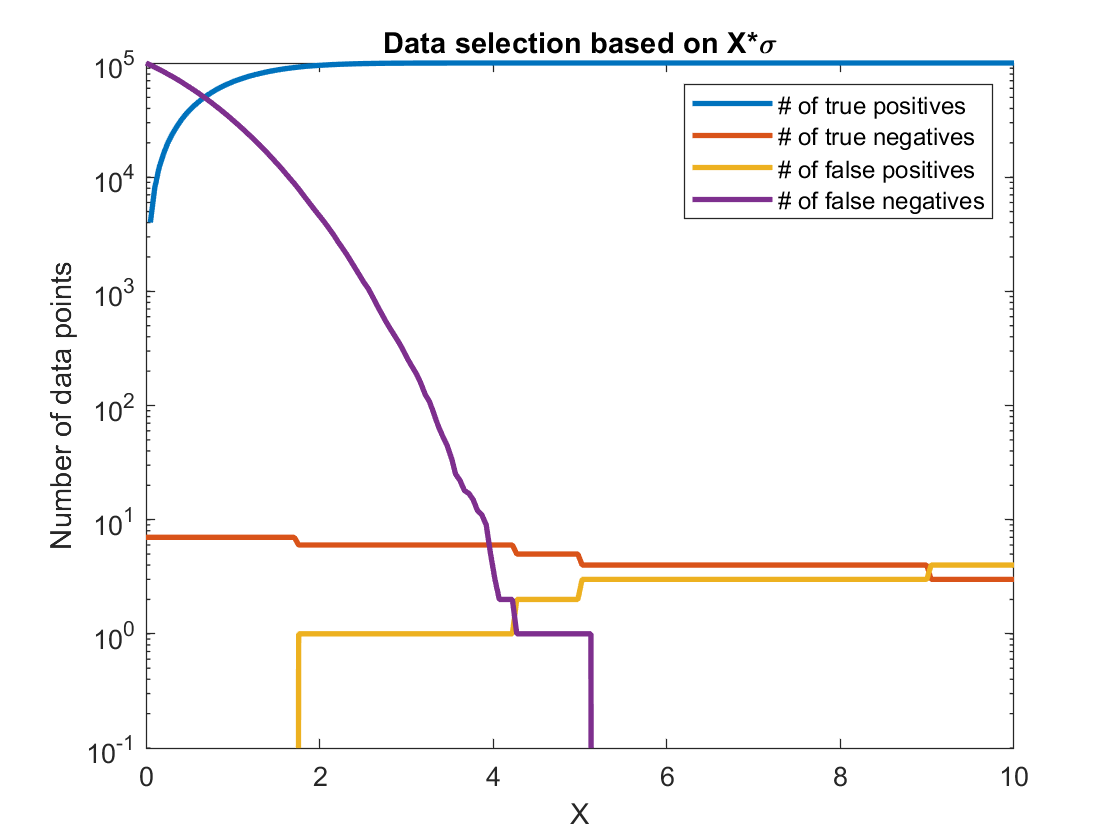

true_pos = [];
true_neg = [];
false_pos = [];
false_neg = [];

X_values = linspace(0, 10, 200);
for ii = X_values
    
    outliers = full_data(full_data < (mu - ii * sig) | full_data > (mu + ii * sig));
    
    clean_data = full_data(~ismember(full_data, outliers));
    
    true_pos = [true_pos, length(intersect(good_data, clean_data))];
    true_neg = [true_neg, length(intersect(bad_data, outliers))];
    false_pos = [false_pos, length(intersect(bad_data, clean_data))];
    false_neg = [false_neg, length(intersect(good_data, outliers))];
    
end

clf;

plot(X_values, true_pos, 'linewidth', 2), hold on;
plot(X_values, true_neg, 'linewidth', 2);

%MATLAB has trouble plotting 0 on a log plot
plot(X_values, false_pos + 1e-23, 'linewidth', 2);
plot(X_values, false_neg + 1e-23, 'linewidth', 2);
set(gca, 'YScale', 'log');
legend('# of true positives', '# of true negatives', '# of false positives', '# of false negatives');
ylim([1e-1 1e5]);
title('Data selection based on {X*\sigma}')
xlabel('{X}');
ylabel("Number of data points");

Looking closely at the individual plots of both the mistakes of omission (false negatives) and true positives, we can see that they seem to follow similar trends:

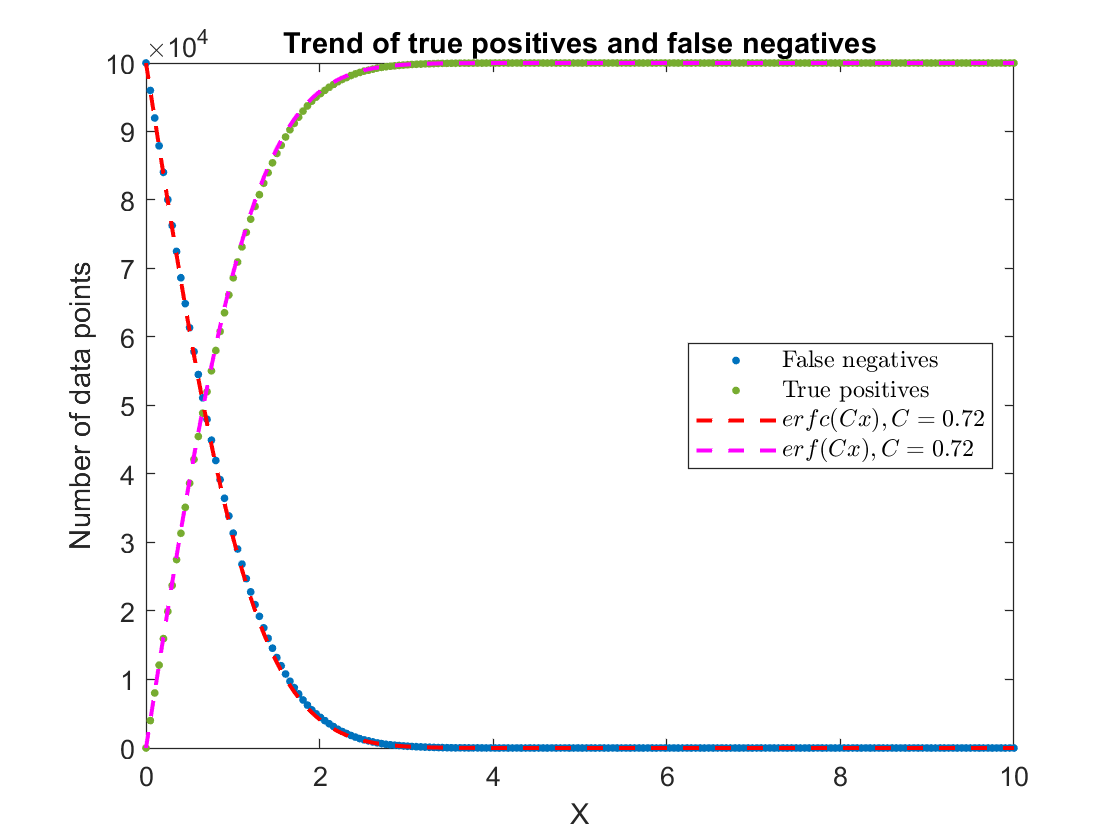

clf;
c = 0.72;
plot(X_values, false_neg, '.', 'MarkerSize', 10), hold on;
plot(X_values, true_pos, '.', 'color', '#77AC30', 'markersize', 10);

plot(X_values, erfc(c .* X_values) .* 1e5, 'r--', 'linewidth', 1.5);
plot(X_values, erf(c .* X_values) .* 1e5, 'm--', 'linewidth', 1.5);
title('Trend of true positives and false negatives')
xlabel('{X}');
ylabel("Number of data points");
legend('False negatives', 'True positives', '$erfc(Cx), C=0.72$', '$erf(Cx), C=0.72 $', 'location', 'east', 'interpreter', 'latex')

We can see that these trends are predictable - the true postitives increase like the error function $erf(Cx)=\frac{2}{\sqrt{\pi}}\int_{0}^{Cx}e^{-t^{2}}\, dt$, while the false negatives decrease like the complementary error function $erfc(Cx)=1-\frac{2}{\sqrt{\pi}}\int_{0}^{Cx}e^{-t^{2}}\, dt$. *C* in both cases is about 0.72, chosen by trial and error to visually match the trend of data. 

When the selection threshold $X*\sigma$ grows large enough to include one more data point, one of two things happens. If the data point is part of the original good data, then the number of true positives increases by 1, and the number of false negatives decreases by 1. If the data point is part of the original bad data, then the number of false positives goes up by 1 and the number of true negatives goes down by 1. Because of this process, the trend of false negatives is complementary to that of true positives, and the same can be said between false positives and true negatives.

As for the mistakes of comission (false positives), we can avoid this happening by having a very low value of X. The number of false positives is 0 for values of X less than around 1.9. However, by doing this we exclude a lot of data - in this range, the number of false negatives is incredibly high (between ${10}^4$ and ${10}^5$).

As stated earlier, we want to minimize the number of false positives and false negatives in our data set. We can ensure this by fining the minimum sum between the number of false positives and false negatives for the entire range of $X$ values:

false_data = false_neg+false_pos;

[min_false, index_false] = min(false_data);
optimal_X = X_values(index_false)

optimal_X = 4.0704

So, we would need a value of X this large to omit the most amount of false positives and false negatives, or mistakes of omission/comission. But we also want to maximize the number of true positives and true negatives in our data:

true_data = true_neg + true_pos;

[max_true, index_true] = max(true_data);
optimal_X = X_values(index_true)

optimal_X = 4.0704

This is the exact same value of X, and not by coincidence; as stated earlier, as X increases, false negatives get converted into true positives and true negatives get converted into false positives at the same rate.

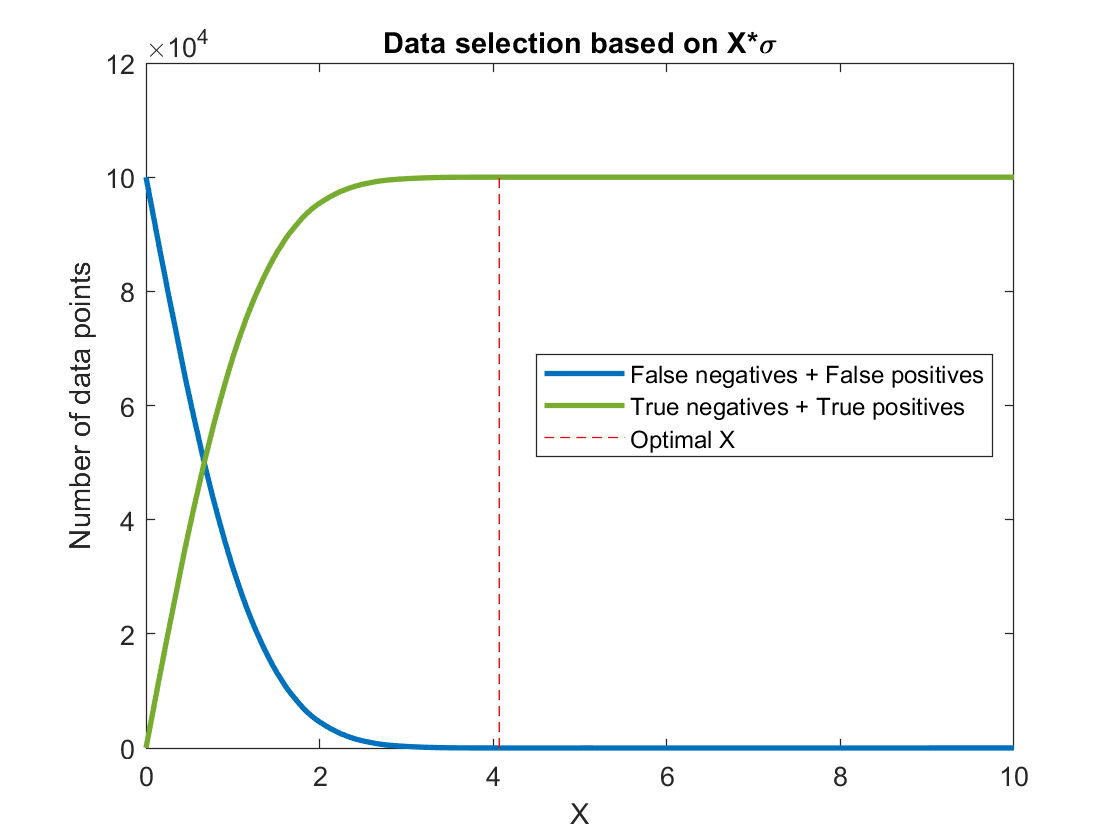

clf;
plot(X_values, false_neg + false_pos, 'linewidth', 2), hold on;
plot(X_values, true_neg + true_pos, '-', 'color', '#77AC30', 'linewidth', 2);
plot([optimal_X, optimal_X], [0, max_true], 'r--')
title('Data selection based on {X*\sigma}')
xlabel('{X}');
ylabel("Number of data points");
legend('False negatives + False positives', 'True negatives + True positives', 'Optimal X', 'location', 'east')

It may seem like the individual plots remain constant after about X = 3, but we can see that they vary slightly. Inspecting the region close to the optimal value of X:

false_data((index_false-3):(index_false+3))

ans =     10     6     4     3     3     3     3


true_data((index_true-3):(index_true+3))

ans =        99997      100001      100003      100004      100004      100004      100004


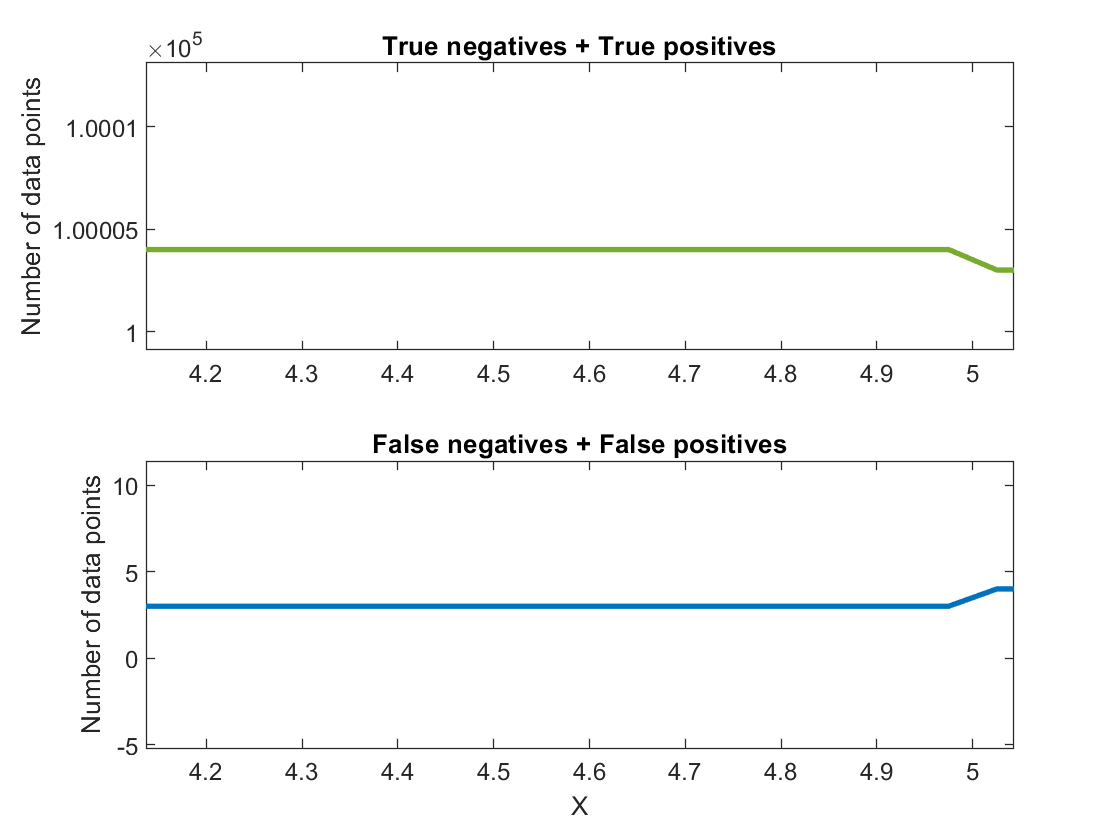

clf;
subplot(2, 1, 1);
plot(X_values, true_neg + true_pos, '-', 'color', '#77AC30', 'linewidth', 2), hold on;
plot([optimal_X, optimal_X], [max_true-10, max_true+10], 'r--'),
xlim([4.137 5.043]);
ylim([99999.1 100013.1]);
title('True negatives + True positives');
ylabel("Number of data points");

subplot(2, 1, 2);
plot(X_values, false_neg + false_pos, 'linewidth', 2), hold on;
plot([optimal_X, optimal_X], [min_false-10, min_false+10], 'r--')
xlim([4.137 5.043]);
ylim([-5.2 11.4]);
title('False negatives + False positives')
xlabel('X');
ylabel("Number of data points");

We see that there exists a range of values of X where the maximum number of true data is accounted for and the minimum number of false data is removed. The optimal value of X we found is the first (or lowest) value of X at which this range begins.

### Problem 2

Here we will be looking for asteroids by observing stationary stars (ignoring proper motion). The position of the star on subsequent images varies due to atmospheric effects or instrumental uncertainties, and this distribution of position can be approximated by a two-dimensional zero-mean Gaussian distribution. The 2-D Gaussian pdf, properly normalized with $\mu =0$ and $\sigma =1$, takes the form $e^{\left(\frac{-x^2 +y^2 }{2}\right)}$.

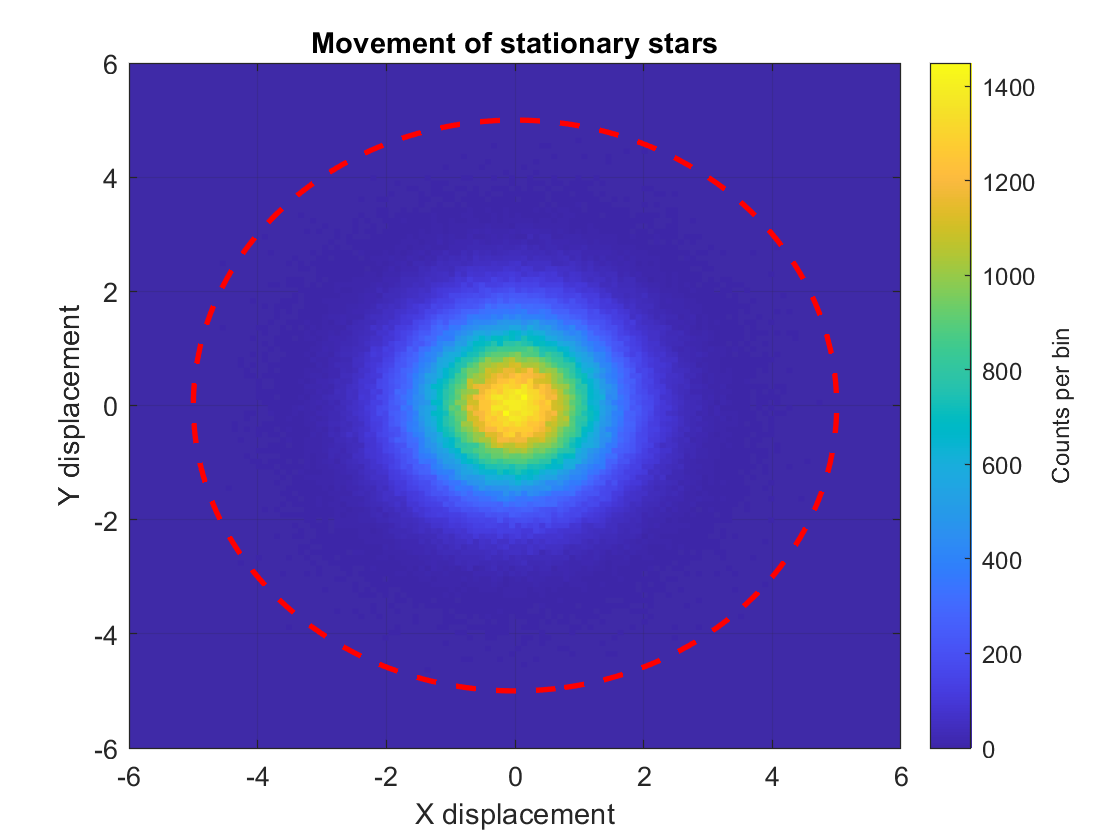

clc;
clear;
clf;

a = random('Normal', 0, 1, [2, 1e6]);
xs = a(1, :);
ys = a(2, :);
histogram2(xs, ys, 100, 'DisplayStyle', 'tile'), hold on;
c = colorbar;
set(gca,'Color','#3F2AA7');
xlim([-6 6])
ylim([-6 6])

r=5;
fimplicit(@(x, y) x.^2 + y.^2 - r .^ 2, 'r--', 'linewidth', 2)
title('Movement of stationary stars')
xlabel('X displacement');
ylabel ('Y displacement');
c.Label.String = "Counts per bin";

We would like to observe a 5-sigma detection of movement to declare that we have observed an asteroid. We would like to find the distance at which this signal would be observed, so we ask the question:

**What is the distance (in arcseconds) away from the origin at which the 2-dimensional Gaussian distribution has a significance of 5 sigma or more?**

We first need to find the probability associated with observing a 5-sigma event on a 2-D Gaussian distribution. We can do this by taking the double integral of the distribution. It is easiest to do this in polar coordinates, where $r$ represents the distance from the origin of the distribution and $\theta$ represents the angle made with the x-axis. Letting $r=\sqrt{x^2 +y^2 }$, the probability is then given by $\int_0^{2\pi } \int_{5\sigma }^{\infty } {r*e}^{\left(\frac{-r^2 }{2}\right)} \mathrm{drd}\theta$.

The outer integral over theta is equal to $2\pi$ since the Gaussian distribution is radially symmetrical; we are considering all angles equally. Furthermore, the radial integral takes the form of a Rayleigh pdf with a scale parameter equal to 1. It is the distribution of the sum of the squares of two randomly distributed variables - $r=\sqrt{x^2 +y^2 }$ - as stated before.

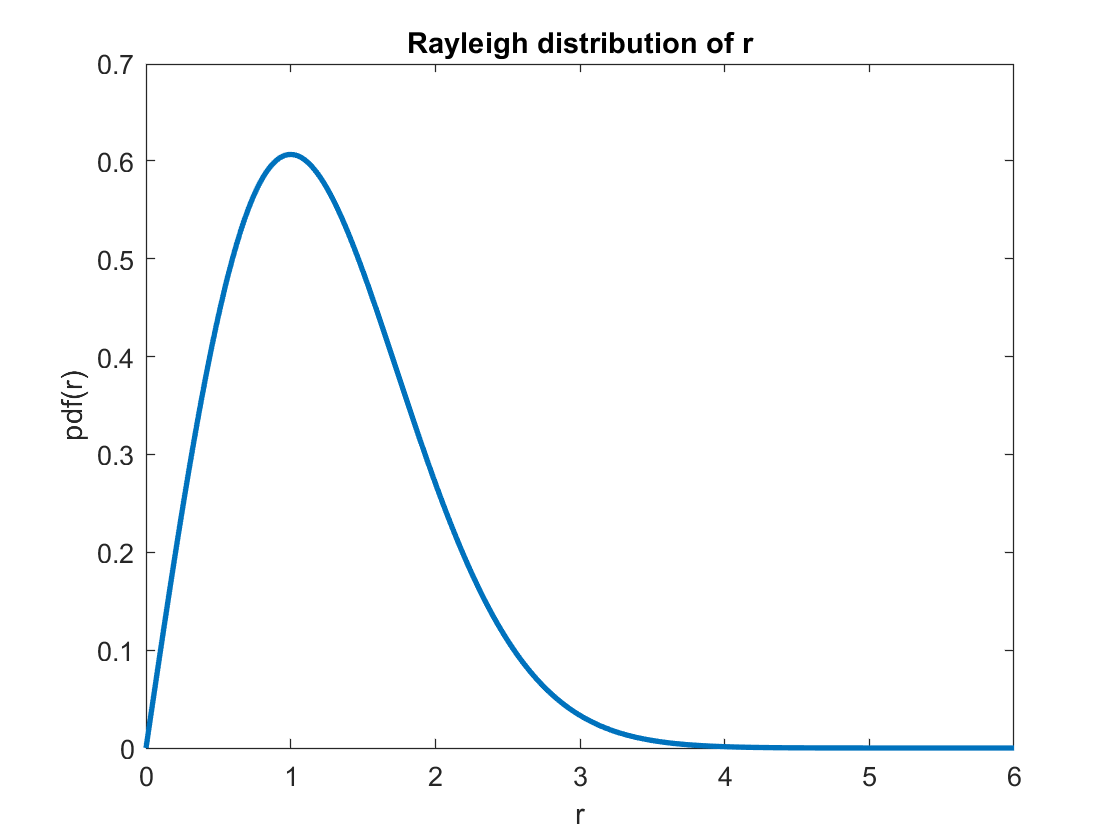

pdfxs = linspace(0, 10, 1000);
pdfys_rayl = raylpdf(pdfxs, 1);

clf;
plot(pdfxs, pdfys_rayl, 'linewidth', 2);
xlim([0 6])
title('Rayleigh distribution of r');
xlabel('r');
ylabel('pdf(r)')

First, we determine what the probability for a 5-sigma event on a 1-D Gaussian distribution is. 

prob_gaussian = 1-normcdf(5, 0, 1)

prob_gaussian = 2.8665e-07

We do this so we can find the *radius at which the probability of a 5-sigma event on a Rayleigh distribution is the same as the probability of a 5-sigma event on a Gaussian distribution*. We can find this simply by computing the value of the inverse cumulative distribution function of the Rayleigh distribution at the probability calculated above:

distance = icdf('Rayleigh', 1-prob_gaussian, 1)

distance = 5.4891

So, if we observed an object 5.5 arcseconds away from the center of the distribution of star positions, it would be significant enough to be a potential asteroid.

### Problem 3.

*Cosmic rays are charged particles—usually protons or electrons but can include atomic nuclei such a alpha particles (helium) or iron. Because of their charge cosmic rays spiral in the magnetic field of the galaxy. From the perspective of the Earth they appear to be coming uniformly from all directions like a high energy gas, and the direction the cosmic ray is travelling when it reaches the Earth tells us nothing about where it came from because we don't know what tortured path it has taken through the galaxy to reach us. However, at trillion electron volt energies and above, the spiral loops are fairly big and the sun and the moon will block cosmic rays. This means the sun and the moon appear as holes in the cosmic ray sky (cosmic rays from that direction are absorbed).*

*Assume a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute (arrivals are random in time). If we can observe where the moon is for 8 hours per night (not too close to the horizon) and we observe for 15 days and see 6800 cosmic rays, what is the signficance of our moon shadow detection?*

Since the cosmic rays arrive independently of one another, randomly in time, we can assume that their distribution over 1 minute forms a Poisson distribution with an average arrival rate $\lambda =1$:

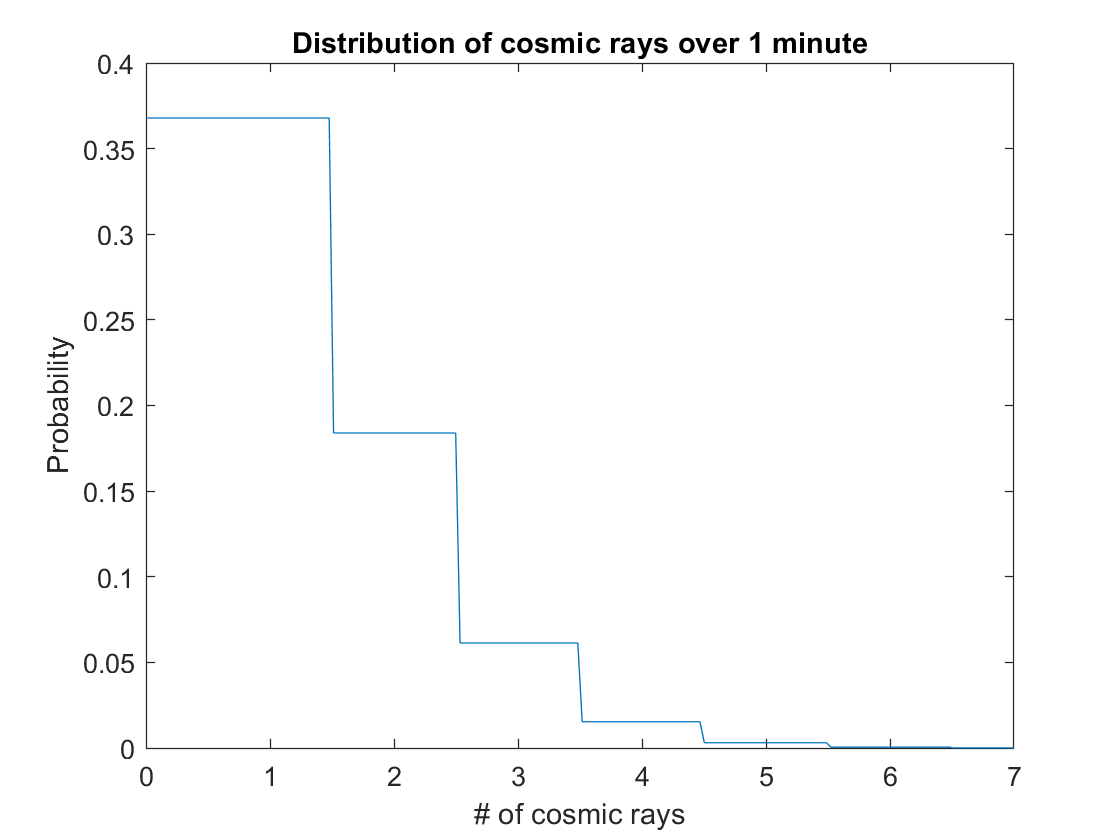

clear;
clc;
clf;

xs = 0:10;
pdf_1min = poisspdf(xs, 1);
xq = linspace(0, 7, 200);
yq = interp1(xs, pdf_1min, xq, 'nearest');

plot(xq, yq);
title('Distribution of cosmic rays over 1 minute');
xlabel('# of cosmic rays');
ylabel('Probability');

If we observe every minute, for 8 hours a day, for 15 days, we will have made 7,200 observations. The resulting pdf for these 7200 observations (15 days) will be equal to the convolution, or sum, of the pdf for 1 minute over 7200 observation intervals.

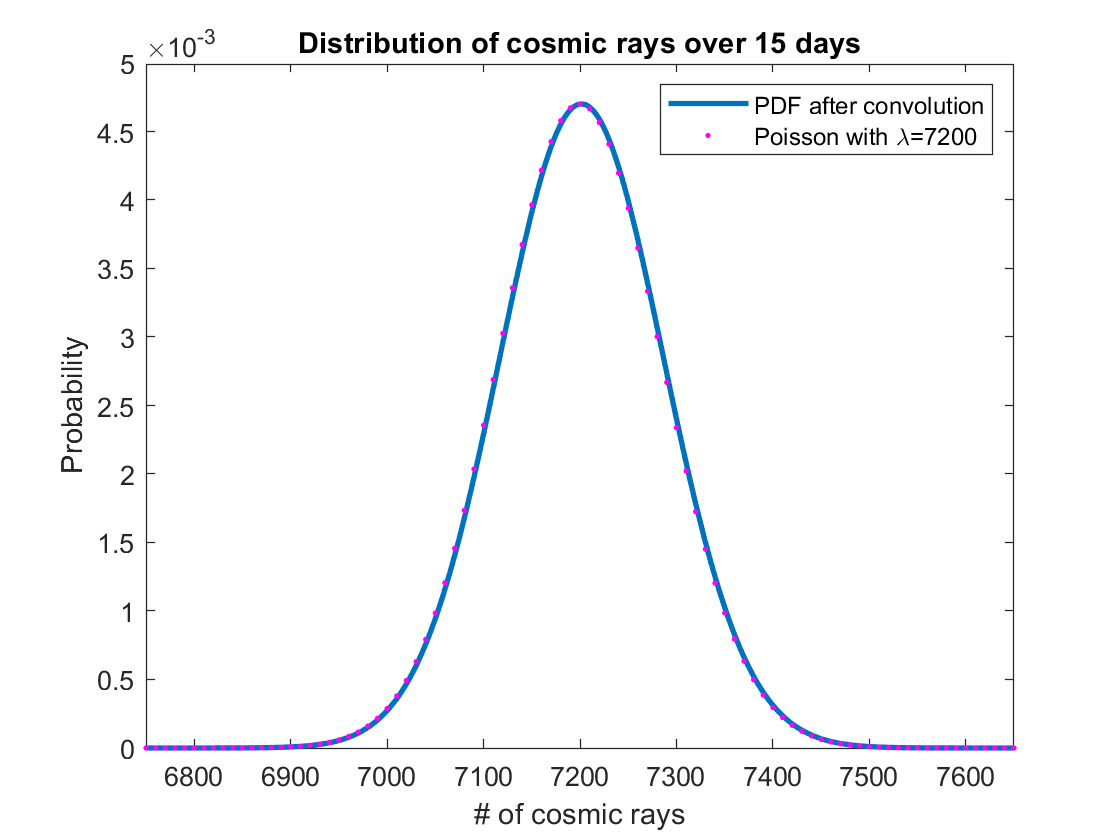

clf;

pdf_15days = pdf_1min;
%not a trials factor, the mean changes
for ii = 1:7200
    pdf_15days = conv(pdf_15days, pdf_1min);
end

xs_15days = 1:length(pdf_15days);
plot(xs_15days, pdf_15days, 'linewidth', 2), hold on;

xs2 = 6500:8000;
ys2 = poisspdf(xs2, 7200);

%better data visualization
xq = 6500:10:8000;
yq = interp1(xs2, ys2, xq);
plot(xq, yq, 'm.')
%

xlim([6750 7650])
title('Distribution of cosmic rays over 15 days');
xlabel('# of cosmic rays');
ylabel('Probability');
legend('PDF after convolution', 'Poisson with {\lambda}=7200')

The distribution is also approximately Gaussian at this point, as predicted by the Central Limit Theorem: as one repeatedly sums a distribution, the resulting distribution approaches a Gaussian distribution.

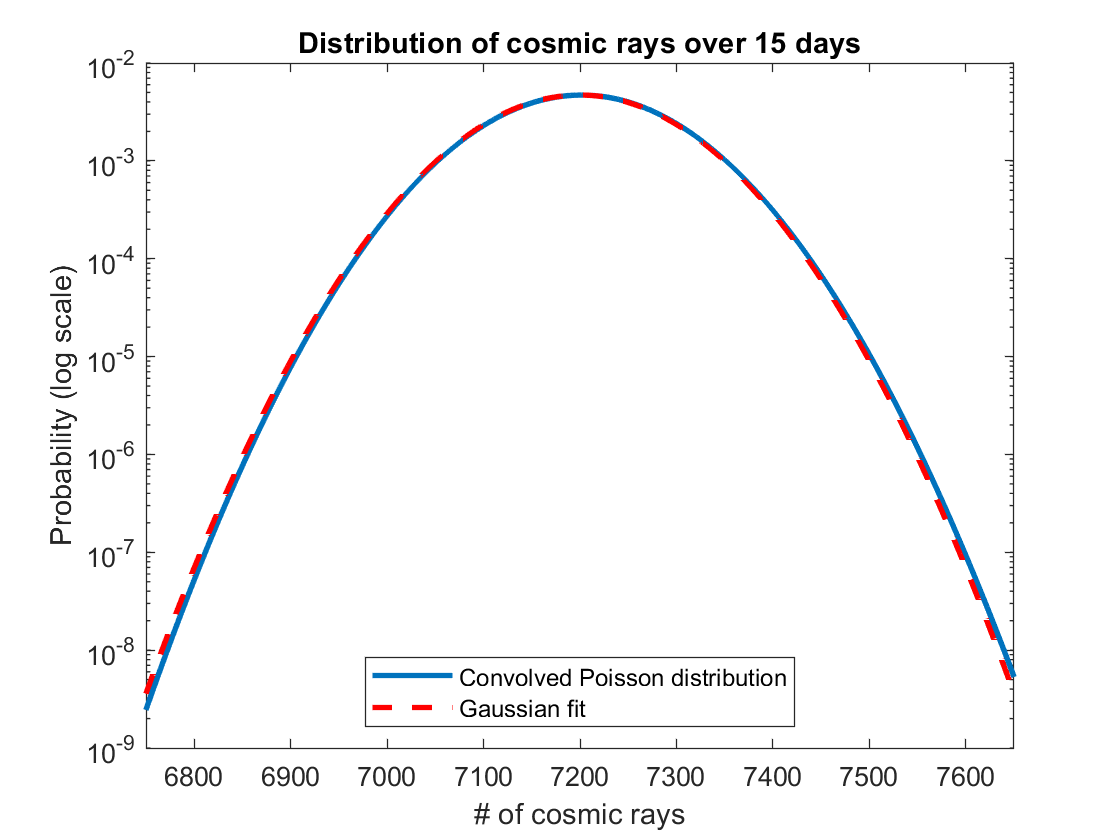

clf;
semilogy(1:length(pdf_15days), pdf_15days, 'linewidth', 2), hold on;
normxs = 6000:8000;
normys = normpdf(normxs, 7200, 84.8);
semilogy(normxs, normys, 'r--', 'linewidth', 2)
xlim([6750 7650])
title('Distribution of cosmic rays over 15 days');
xlabel('# of cosmic rays');
ylabel('Probability (log scale)');
legend('Convolved Poisson distribution', 'Gaussian fit', 'location', 'south')

An interesting property about Poisson distributions is that the convolution of multiple Poisson distributions [is a Poisson distribution with](https://en.wikipedia.org/wiki/List_of_convolutions_of_probability_distributions#Discrete_distributions) $\lambda_i =\sum_{i=1}^n \lambda_i$, that is, a Poisson distribution with $\lambda$ equal to the sum of the $\lambda$s of the convolved distributions. Thus, the convolved distribution over 15 days is equivalent to a Poisson distribution with $\lambda =N*\lambda_i =7200$.

After observing for 15 days, we observe 6800 cosmic rays, while on average we would expect 7200. This indicates a significant drop in the number of cosmic rays we receive, and we want to know if this is caused by the moon blocking some of the rays from reaching the Earth. We want to solve the following statistical question: **What is the probabilty that we observe 6800 cosmic rays or fewer based on the distribution of expected cosmic ray observations?**

To solve this question, all we need to do is perform a discrete sum of the Poisson pdf from 0 to 6800: $P\left(<6800\right)=\sum_{k=0}^{6800} \frac{\lambda^k e^{-\lambda } }{k!}$. This is equivalent to reading the value of the cumulative distribution function for this Poisson distribution at k = 6800:

probability = poisscdf(6800, 7200)

probability = 1.0133e-06

The probability that we would observe such a small number of cosmic rays from an average distribution is very small - on the order of ${10}^{-6}$.

sigma = abs(norminv(probability))

sigma = 4.7507

While this probability is extremely small, it is not quite significant enough to be considered a significant discovery - 5 sigma in most physics applications.